# 2.4 系统函数：差分方程 ↔ H(z)，收敛域与稳定，频率响应的几何确定法，IIR 与 FIR

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end
th = linspace(0, 2*pi, 400); unitCircle = [cos(th); sin(th)];

## 演示1：差分方程 → 系统函数 → 零极点（教材 2.4.1—2.4.3）

y(n) − 1.2y(n−1) + 0.72y(n−2) = x(n) + x(n−1) ⇒ H(z) = (1 + z^{-1}) / (1 − 1.2z^{-1} + 0.72z^{-2})

b = [1 1]; a = [1 -1.2 0.72];
zeros_ = roots(b); poles_ = roots(a);               % 零点 −1；极点 0.6 ± 0.6j，|p| = 0.85
N = 40; imp = [1 zeros(1, N-1)];
hImp = filter(b, a, imp);                           % 单位采样响应，按差分方程递推
w = linspace(0, pi, 801); z = exp(1i*w);
Hz = @(z) polyval(b, z) ./ polyval(a, z) .* z.^(numel(a)-numel(b));   % H(z)：分子分母按 z^{-1} 多项式求值
Hw = polyval(fliplr(b), z.^-1) ./ polyval(fliplr(a), z.^-1);          % 直接用 z^{-1} 形式
% 核对差分方程：用 h 作输入 x=δ 时，递推关系每一步成立
lhs = hImp - 1.2*[0 hImp(1:end-1)] + 0.72*[0 0 hImp(1:end-2)]; rhs = imp + [0 imp(1:end-1)];

## 演示2：频率响应的几何确定法（教材 2.4.4）

`H(e^{jω})` = ∏|e^{jω} − 零点| / ∏|e^{jω} − 极点|；ω 靠近极点角度时分母短 → 峰；ω=π 落在零点上 → 零

geo = @(wq) abs(prod(exp(1i*wq) - zeros_)) / abs(prod(exp(1i*wq) - poles_));
Hgeo = arrayfun(geo, w);
wMark = pi/4; zm = exp(1i*wMark);                   % 在 ω=π/4 画出从零极点到单位圆点的向量
errGeo = max(abs(Hgeo - abs(Hw)));

## 演示3：收敛域与稳定性——极点在单位圆内，因果系统才稳定

aUnstable = [1 -1.2];                               % y(n) = 1.2 y(n−1) + x(n)：极点 1.2 在单位圆外
hUnstable = filter(1, aUnstable, imp);
sumStable = sum(abs(hImp)); hLong = filter(b, a, [1 zeros(1, 399)]); tailStable = sum(abs(hLong(201:end)));

## 演示4：IIR 与 FIR（教材 2.4.5，例 2.10 的横向滤波器）

h(n) = a1^n，0≤n≤M−1：零点在 `z`=a1 的圆上 M 等分，z=a1 处被极点抵消。a1=1 就是 M 点滑动平均。

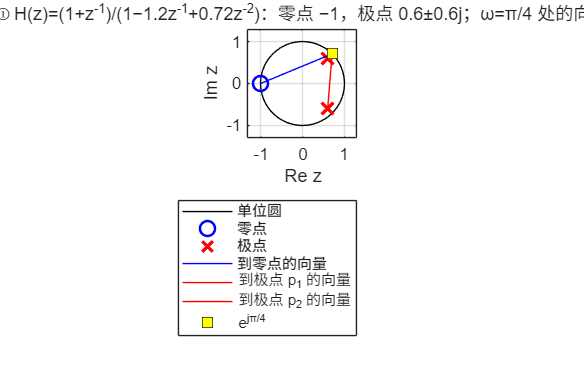

a1 = 0.9; Mt = 8; hT = a1.^(0:Mt-1);
zT = roots(hT);                                     % M−1 个零点
hMA = ones(1, 4)/4;                                 % a1=1，M=4：四点滑动平均（第 7 章 FIR-01 实验的系统）
zMA = roots(hMA);                                   % 4 次单位根除去 z=1：j, −1, −j
HMA = abs(polyval(fliplr(hMA), z.^-1));            % 零点对应 ω = π/2, π（f_s=1000 Hz 时 250、500 Hz）

if ~LIVE, f1 = figure('Name','01 系统函数','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); plot(unitCircle(1,:), unitCircle(2,:), 'k'); hold on;
plot(real(zeros_), imag(zeros_), 'bo', 'MarkerSize', 9, 'LineWidth', 1.5); plot(real(poles_), imag(poles_), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
plot([real(zeros_) real(zm)], [imag(zeros_) imag(zm)], 'b-'); plot([real(poles_)'; real(zm)*[1 1]], [imag(poles_)'; imag(zm)*[1 1]], 'r-');
plot(real(zm), imag(zm), 'ks', 'MarkerSize', 8, 'MarkerFaceColor', 'y'); axis equal; grid on; xlim([-1.3 1.3]); ylim([-1.3 1.3]);
title('① H(z)=(1+z^{-1})/(1−1.2z^{-1}+0.72z^{-2})：零点 −1，极点 0.6±0.6j；ω=π/4 处的向量'); xlabel('Re z'); ylabel('Im z');
legend('单位圆','零点','极点','到零点的向量','到极点 p_1 的向量','到极点 p_2 的向量','e^{jπ/4}');

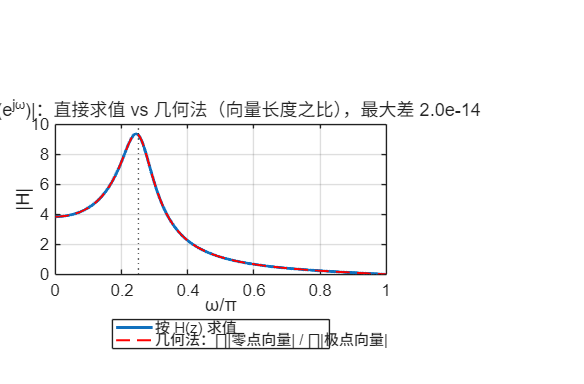

newpanel(); plot(w/pi, abs(Hw), 'LineWidth', 1.8); hold on; plot(w/pi, Hgeo, 'r--', 'LineWidth', 1.2);
xline(abs(angle(poles_(1)))/pi, ':'); grid on;
title(sprintf('② |H(e^{jω})|：直接求值 vs 几何法（向量长度之比），最大差 %.1e', errGeo)); xlabel('ω/π'); ylabel('|H|');
legend('按 H(z) 求值','几何法：∏|零点向量| / ∏|极点向量|');

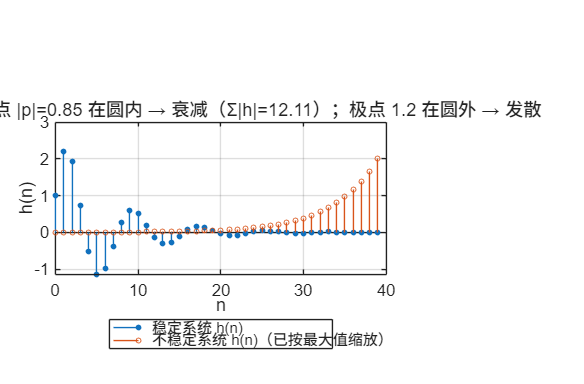

newpanel(); stem(0:N-1, hImp, 'filled', 'MarkerSize', 3); hold on; stem(0:N-1, hUnstable/max(hUnstable)*2, 'MarkerSize', 3, 'Color', [0.85 0.33 0.1]);
grid on; xlim([0 N]);
title(sprintf('③ h(n)：极点 |p|=0.85 在圆内 → 衰减（Σ|h|=%.2f）；极点 1.2 在圆外 → 发散', sumStable));
xlabel('n'); ylabel('h(n)'); legend('稳定系统 h(n)','不稳定系统 h(n)（已按最大值缩放）');

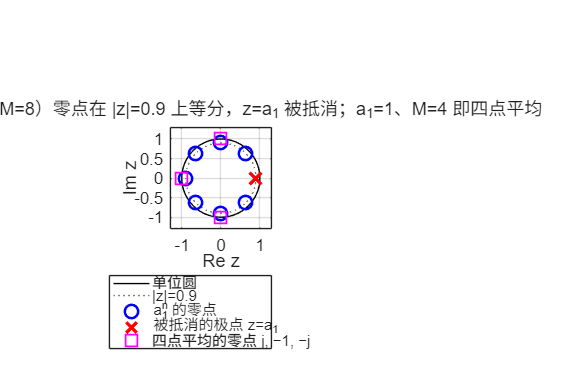

newpanel(); plot(unitCircle(1,:), unitCircle(2,:), 'k'); hold on; plot(a1*cos(th), a1*sin(th), ':', 'Color', [0.5 0.5 0.5]);
plot(real(zT), imag(zT), 'bo', 'MarkerSize', 8, 'LineWidth', 1.5); plot(a1, 0, 'rx', 'MarkerSize', 10, 'LineWidth', 2);
plot(real(zMA), imag(zMA), 'ms', 'MarkerSize', 9, 'LineWidth', 1.5); axis equal; grid on; xlim([-1.3 1.3]); ylim([-1.3 1.3]);
title(sprintf('④ FIR：a_1^n（M=%d）零点在 |z|=%.1f 上等分，z=a_1 被抵消；a_1=1、M=4 即四点平均', Mt, a1));
xlabel('Re z'); ylabel('Im z'); legend('单位圆','|z|=0.9','a_1^n 的零点','被抵消的极点 z=a_1','四点平均的零点 j, −1, −j');

if ~LIVE, sgtitle('差分方程 ↔ H(z) ↔ 零极点 ↔ 频率响应；极点在圆内才稳定；FIR 的零点排在圆上'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '04-system-function.png'), 'Resolution', 150); end

## 教师核验

assert(max(abs(lhs - rhs)) < 1e-12, 'h(n) 不满足差分方程');
assert(max(abs(abs(Hw) - abs(Hz(z)))) < 1e-12, '两种 H(z) 求值不一致');
assert(errGeo < 1e-10, '几何法与直接求值不一致');
assert(abs(abs(poles_(1)) - sqrt(0.72)) < 1e-12 && abs(zeros_ + 1) < 1e-12, '零极点位置不符');
assert(tailStable < 1e-6 && abs(hUnstable(end)/hUnstable(end-1) - 1.2) < 1e-9, '稳定性判断不符');
assert(max(abs(sort(abs(zT)) - a1)) < 1e-9, '横向滤波器零点应在 |z|=a1 上');
angMA = sort(mod(angle(zMA), 2*pi)); assert(max(abs(angMA - [pi/2; pi; 3*pi/2])) < 1e-9, '四点平均零点应为 j, −1, −j');   % 用 [0,2π) 比较，避免 ±π 歧义
assert(HMA(1) == 1 && HMA(round(numel(w)/2)) < 1e-12 && HMA(end) < 1e-12, '四点平均在 DC 为 1、在 π/2 与 π 为 0');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'b', b, 'a', a, 'zeros_real', real(zeros_), 'poles_real', real(poles_), 'poles_imag', imag(poles_), 'pole_radius', abs(poles_(1)), ...   % jsonencode 不支持复数
    'geometric_vs_direct_max_err', errGeo, 'sum_abs_h_stable', sumStable, 'tail_abs_h_stable_after_200', tailStable, ...
    'unstable_pole', 1.2, 'transversal_a1', a1, 'transversal_M', Mt, 'transversal_zero_radius', mean(abs(zT)), ...
    'moving_average_4_zero_angles_over_pi', angMA/pi, 'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-system.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

                          matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                                  run_at: '2026-09-18 19:30:26'
                                       b: [1 1]
                                       a: [1 -1.2000 0.7200]
                              zeros_real: -1
                              poles_real: [2×1 double]
                              poles_imag: [2×1 double]
                             pole_radius: 0.8485
             geometric_vs_direct_max_err: 1.9540e-14
                        sum_abs_h_stable: 12.1092
             tail_abs_h_stable_after_200: 6.5611e-14
                           unstable_pole: 1.2000
                          transversal_a1: 0.9000
                           transversal_M: 8
                 transversal_zero_radius: 0.9000
    moving_average_4_zero_angles_over_pi: [3×1 double]
                       all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results



function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end